# Generate Data: Simple Example

clear;clc;
addpath("gendata_helper");
addpath("Tools");


We assume that the communication between agents are shown in graph.

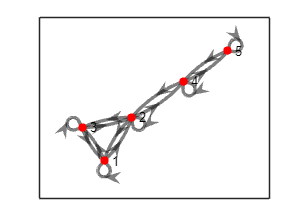


A=[1,1,1,0,0;
    1,1,1,1,0;
    1,1,1,0,0;
    0,1,0,1,1;
    0,0,0,1,1];
G=digraph(A);
plot(G,'LineWidth',2,'EdgeColor','k','NodeColor','r','Layout','auto','ArrowSize',10,'layout','auto')

## Generate Trajectory for Each Robot

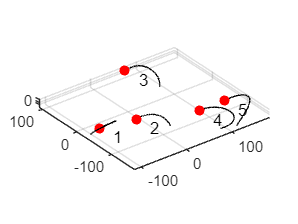

% 1. Temporal parameters
T_WORKING=10; %
dti=0.01; %The sample interval of the IMU/estimator(s), i.e. IMU's frequency is 100Hz

scale=1;
% 
sigma_bg=0.01; 
sigma_ba=0.01; 
sigma_a=0.05; %%0.01
sigma_g=0.05;


% % 
% sigma_bg=0.01; 
% sigma_ba=0.01; 
% sigma_a=0.01; 
% sigma_g=0.01;


% sigma_bg=0.01; 
% sigma_ba=0.01; 
% sigma_a=0.01; %%0.01
% sigma_g=0.01;
b_g_real=[0.02,0.01,0.02];%bias 
b_a_real=[0.03,0.05,0.03];
g_real=[0;0;-9.81];

%3. Effective measurement range (about landmark)
Eff_Range=150;

%4. Trajectory setting
% Assign initial positions for robots
Position0=[-80,-60,0; 
            -10,-75,0; 
            75,69,2; 
            90,-125,5;
            150,-120,2];

% Generate many landmarks
% 极端情况，有些根本看不到一个路标
if(0)
N_LANDMARKS=100;
landm_pos=11*randn(N_LANDMARKS,3)+Position0(1,:);
landmarks=[];
end

% 正常情况，路标非均匀分布，但是每个人身边都有一些些，但是每个的传感器协方差不一样哦
NL1=45;
NL2=15;
NL3=20;
NL4=10;
NL5=10;
landm_pos1=12*randn(NL1,3)+Position0(1,:);
landm_pos2=6*randn(NL2,3)+Position0(2,:);
landm_pos3=8*randn(NL3,3)+Position0(3,:);
landm_pos4=13*randn(NL4,3)+Position0(4,:);
landm_pos5=15*randn(NL5,3)+Position0(5,:);
landm_pos=[landm_pos1;landm_pos2;landm_pos3;landm_pos4;landm_pos5];
N_LANDMARKS=NL1+NL2+NL3+NL4+NL5;


for uu=1:N_LANDMARKS
    T_f=eye(4);
    Rot1=randn(1,1)*3.14;
    Rot2=randn(1,1)*3.14;
    Rot3=randn(1,1)*3.14;
    Rot=angle2dcm(Rot1,Rot2,Rot3);
    T_f(1:3,1:3)=Rot;
    T_f(1:3,4) = landm_pos(uu,:)';
    landmarks(uu).T = T_f;
end

%%debug only focus on one robot
trigK=[4.5, 1,  1.5;
       2.0,2.0, 3;
       2.5,2.5,4.5; 
       3.5,3.5,2.5;
       4.5,3,3.5]; % parameters about trajectory
Robot=[];
for i=1:5
    num=num2str(i);
    [Robot(i).real_path,Robot(i).T_real0] = gen_trajectory(T_WORKING, dti, Position0(i,:),trigK(i,:),num);
    axis equal
    Robot(i).IMU_data = IMU_gendata(Robot(i).real_path,b_g_real,b_a_real,sigma_g, sigma_a, dti);
end

## Generate measurements about the landmark

We assume that the whole system keep a fixed frequency to interchange their information. 

i.e., at the same time ("system update time"), there will be agent-to-feature measurement and agent-to-agent measurement.

The system is dynamic, and only in the effective range then agents can see the feature.

% sigma_if=0.0002*ones(5,1);
% sigma_ij=0.0002*ones(5,1);

sigma_if=[0.02,0.01,0.01,0.05,0.05];
sigma_ij=[0.03,0.02,0.02,0.02,0.02];


dt_update=0.02;
% m_data=gen_measurement_SE3(Eff_Range, T_feature, A, sigma_if, sigma_ij, trigK, Position0, T_WORKING, dt_update);
m_data=gen_measurement_SE3(Eff_Range, landmarks, A, sigma_if, sigma_ij, trigK, Position0, T_WORKING, dt_update);

### Save New Data

folder='dataset'; 
if exist(folder)==0 
    mkdir(folder); 
end

save("dataset/data66.mat");

